print = 0;
chosen = 57;
offset = 15;
day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(chosen,:);
E_max = Storage_size(5);
% [optimal_Eg_0, Prediction_in_MWH, Prediction_in_MWH_max]
%% Real Load
[optimal_Eg_Real, Lower_Bound_Real, Higher_Bound_Real] = Energy_Bands_func(day_to_predict_in_2023(offset+1:end),sigma2023,mu2023,E_max,print);


%% LSTM Prediction
[optimal_Eg_LSTM, Lower_Bound_LSTM, Higher_Bound_LSTM] = Energy_Bands_func(Predictions_LSTM_2023(chosen,:),sigma2023,mu2023,E_max,print);



%% ARIMAX Prediction
% Predictions_ARIMAX_2023_transposed = (Predictions_ARIMAX_2023_transposed - mu_arima) ./ sigma_arima;
[optimal_Eg_ARIMAX, Lower_Bound_ARIMAX, Higher_Bound_ARIMAX] = Energy_Bands_func(Predictions_ARIMAX_2023_transposed(chosen,:),sigma_arima,mu_arima,E_max,print);



dt = 0.25; % hr
T = 24;
t = (T - dt*(length(Predictions_ARIMAX_2023_transposed(chosen,:)) - 1)):dt:T;

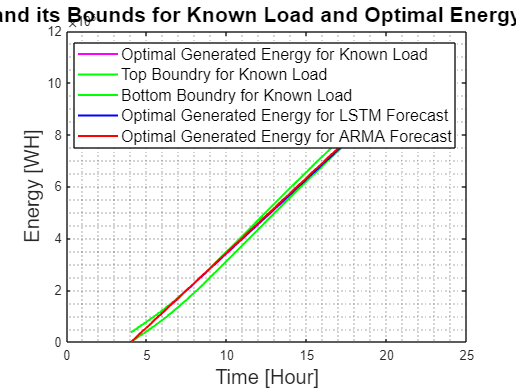


figure
plot(t, optimal_Eg_Real,'m','LineWidth',1.5)
hold on
plot(t, Lower_Bound_Real,'g','LineWidth',1.5)
plot(t, Higher_Bound_Real,'g','LineWidth',1.5)
plot(t, optimal_Eg_LSTM,'b','LineWidth',1.5)
plot(t, optimal_Eg_ARIMAX,'r','LineWidth',1.5)

title('The Optimal Generated Energy and its Bounds for Known Load and Optimal Energy for LSTM and ARMA Forecasting', 'FontSize', 16)
xlabel('Time [Hour]', 'FontSize', 15)
ylabel('Energy [WH]', 'FontSize', 15)
legend('Optimal Generated Energy for Known Load','Top Boundry for Known Load','Bottom Boundry for Known Load','Optimal Generated Energy for LSTM Forecast','Optimal Generated Energy for ARMA Forecast', 'FontSize', 12)
grid minor